Optimal LQ RL Inverted Pendulum on a Cart Demo

clear all; close all;
clc

Input Data: State Space Matrices

A=[0 0 1 0; 0 0 0 1; 0 40.2 -14.53 0; 0 82.56 -15.77 0];
B=[0;0;27.28;26.74];
C=[1 0 0 0;0 1 0 0];
D=[0;0];
x0=[1;1;1;1];% assumed initial condition

LQ Optimal Control

R1=[10 0 0 0; 0 1 0 0; 0 0 0 0; 0 0 0 0];
R2=20;

Controllability and Observability Tests

CO=ctrb(A,B); rankCO=rank(CO) 

rankCO = 4

OM=obsv(A,R1); rankOM=rank(OM) 

rankOM = 4

Direct Solution of the Optimal LQ Problem

[Fopt,P]=lqr(A,B,R1,R2);
Jopt=0.5*x0'*P*x0

Jopt = 209.1142

Reinforcement Learning Solution of the Optimal LQ Problem

ev=eig(A);
lambda_desired=[-5; - 10; -20+j*15; -20-j*15]; 
F0=place(A,B,lambda_desired);

Vaisbod-Milstein-Kleinman Reinforcer

R2I=inv(R2);
iter = 5;
for i=1:iter
    Pi=lyap((A-B*F0)',R1+F0'*R2*F0);
     i
    Ji(i)=0.5*x0'*Pi*x0
    F0=R2I*B'*Pi;
    model=sim(pendulum)

    time_itr(1:length(model.t),i) = model.t;
    X_1(1:length(model.t),i) = model.x(:,1);
    X_2(1:length(model.t),i) = model.x(:,2);
    X_3(1:length(model.t),i) = model.x(:,3);
    X_4(1:length(model.t),i) = model.x(:,4);
end

i = 1

model =   Simulink.SimulationOutput:

                      t: [60x1 double] 
                   tout: [60x1 double] 
                      x: [60x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


i = 2

Ji =   886.8558  520.0401


model =   Simulink.SimulationOutput:

                      t: [59x1 double] 
                   tout: [59x1 double] 
                      x: [59x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


i = 3

Ji =   886.8558  520.0401  348.9477


model =   Simulink.SimulationOutput:

                      t: [59x1 double] 
                   tout: [59x1 double] 
                      x: [59x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


i = 4

Ji =   886.8558  520.0401  348.9477  265.5725


model =   Simulink.SimulationOutput:

                      t: [59x1 double] 
                   tout: [59x1 double] 
                      x: [59x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


i = 5

Ji =   886.8558  520.0401  348.9477  265.5725  226.3736


model =   Simulink.SimulationOutput:

                      t: [58x1 double] 
                   tout: [58x1 double] 
                      x: [58x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


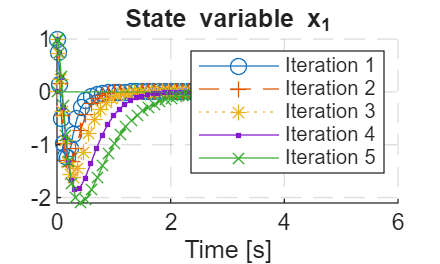

markers = {'o', '+', '*', '.', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
lineStyles = {'-', '--', ':', '-.'};

figure (1)
 for i=1:iter
     hold on
     Iname_1 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X_1(:,i),'Marker',markers{mod(i,iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_1)
   
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_1')
legend;

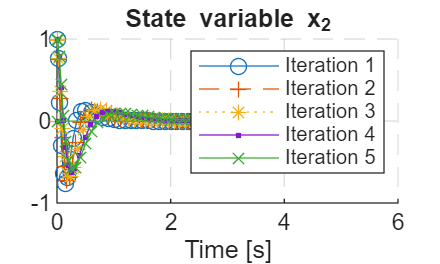


figure (2)
 for i=1:iter
     hold on
     Iname_2 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X_2(:,i),'Marker',markers{mod(i,iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_2)
 end
 grid on
 set(gca,'GridLineStyle','--')
 legend; xlabel('Time [s]');title('State variable x_2')

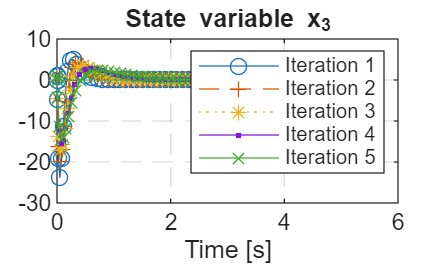


 figure (3)
  for i=1:iter
     Iname_3 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X_3(:,i),'Marker',markers{mod(i,iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_3)
     hold on
 end
grid on
set(gca,'GridLineStyle','--')
legend; xlabel('Time [s]');title('State variable x_3')

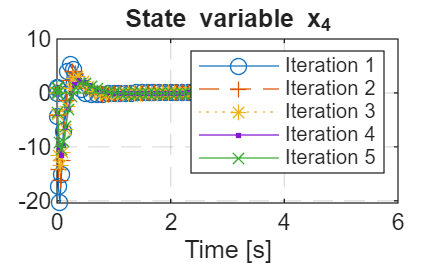


figure (4)
 for i=1:iter
     Iname_4 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X_4(:,i),'Marker',markers{mod(i,iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_4)
     hold on
 end
grid on
set(gca,'GridLineStyle','--')
legend; xlabel('Time [s]');title('State variable x_4')